clearvars;
close all;
N = 2^10;
T = 2.697200567700154e+001;
t0 = 0 ;

h = (T - t0)/N;
U = zeros(2,N);

U(1) = pi/3;
U(2) = 0;

for i = (1:N-1)
    U(:,i+1) = U(:,i)  + h*fun(U(:,i));
end



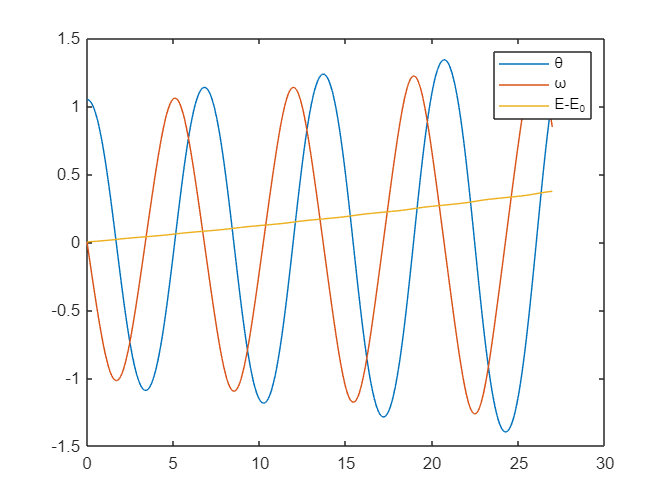

t = t0 + h*(0:N-1);
er  = U(2,:).^2 / 2 + (cos(U(1))-cos(U(1,:)));

plot(t,U(1,:))
hold on 
plot(t,U(2,:))
plot(t,er)
legend('\theta','\omega','E-E_0')
hold off

clearvars;
close all;
N = 2^10;
T = 2.697200567700154e+001;
t0 = 0 ;

h = (T - t0)/N;
U = zeros(2,N);

U(1) = pi/3;
U(2) = 0;

for i = (1:N-1)
    U(:,i+1) = U(:,i)  + fun2(U(:,i),h);
end

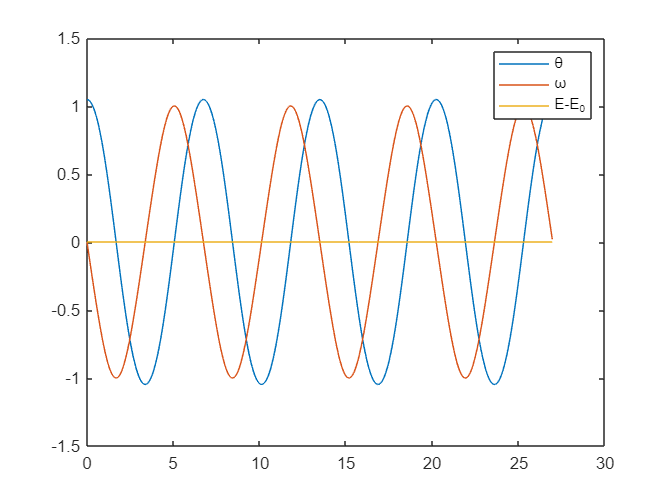

t = t0 + h*(0:N-1);
er  = U(2,:).^2 / 2 + (cos(U(1))-cos(U(1,:)));

plot(t,U(1,:))
hold on 
plot(t,U(2,:))
plot(t,er)
legend('\theta','\omega','E-E_0')
hold off

function res = fun(u)
    theta = u(1);   
    w = u(2);
    res = [w,-sin(theta)]';
    
end

function res = fun2(u,h)
    theta = u(1);   
    w = u(2);
    
    res = h*[w - h/2 *sin(theta),-sin(theta) - h/2 * w*cos(theta)]';
end


